# Chapitre 7 : Optimum filters

## Ex7.6 : Kalman filter - Truck on rail

Consider a truck on frictionless, straight rails. Initially, the truck is stationary at position 0, but it is buffeted this way and that by a random uncontrolled forces with non zero mean (trend). We measure the position of the truck every $\Delta t$ seconds, but these measurements are imprecise

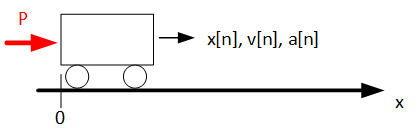

We want to maintain a model of where the truck is (position $x[n]$) and what is its velocity ($v[n]$) of a truck every $\Delta t$ [s].


$$X\left\lbrack n\right\rbrack =\left\lbrack \begin{array}{c}
x\left\lbrack n\right\rbrack \\
v\left\lbrack n\right\rbrack 
\end{array}\right\rbrack$$


The truck is pushed by a uniformely random force which creates a $\mu_a =2\;\left\lbrack \frac{m}{s^2 }\right\rbrack$ mean accelaration with a standard deviation of $\sigma_a =2\;\left\lbrack \frac{m}{s^2 }\right\rbrack$. The sampling period is 100 [ms].

The position of the truck is measured with a high noise with a standard deviation of $\sigma_v =100\;\left\lbrack m\right\rbrack$

clear; close all;
rng default;

## Generate trajectory

### Parameters

Based on the description, the following parameters are defined:

### Generation

We can write the motion equations:


$$\left\lbrace \begin{array}{ll}
x\left\lbrack n\right\rbrack  & =x\left\lbrack n-1\right\rbrack +v\left\lbrack n-1\right\rbrack \cdot \Delta t+\frac{1}{2}{\left(\Delta t\right)}^2 a\left\lbrack n-1\right\rbrack \\
v\left\lbrack n\right\rbrack  & =v\left\lbrack n-1\right\rbrack +\Delta t\cdot a\left\lbrack n-1\right\rbrack 
\end{array}\right.$$


They can be written in matrix shape:


$$\left\lbrack \begin{array}{c}
x\left\lbrack n\right\rbrack \\
v\left\lbrack n\right\rbrack 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & \Delta t\\
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\left\lbrack n-1\right\rbrack \\
v\left\lbrack n-1\right\rbrack 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\frac{1}{2}\Delta t\\
\Delta t
\end{array}\right\rbrack a\left\lbrack n-1\right\rbrack$$


or in compact shape:


$$\mathit{\mathbf{X}}\left\lbrack n\right\rbrack =\mathit{\mathbf{F}}\cdot \mathit{\mathbf{X}}\left\lbrack n-1\right\rbrack +\mathit{\mathbf{B}}\cdot a\left\lbrack n-1\right\rbrack \;$$


where a[n] is a uniformy distributed noise with non nul mean $\mu_a$ and variance of $\sigma_a$.

And the only the position of the truck is measured.


$$z\left\lbrack n\right\rbrack =\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\left\lbrack n\right\rbrack \\
v\left\lbrack n\right\rbrack 
\end{array}\right\rbrack +\textrm{vn}\left\lbrack n\right\rbrack$$


Or in compact shape:


$$z\left\lbrack n\right\rbrack =\mathit{\mathbf{H}}\cdot \;\mathit{\mathbf{X}}\left\lbrack n\right\rbrack +\textrm{vn}\left\lbrack n\right\rbrack$$


Where $\textrm{vn}$[n] is the measurement noise which is normally distributed with zero mean and a variance of $\sigma_v^2$.

### Generation

Based on the previous equations, the truck position is generated.

## Kalman Filter

### Kalman matrices

The previous already defined the matrices **F**, **B**, and **H**.

Only the covariance matrix for the process noise and the measurement are missing. The covariance matrix of the process is :


$${\mathit{\mathbf{Q}}}_w =\mathit{\mathbf{G}}\cdot {\mathit{\mathbf{G}}}^T \sigma_a^2$$


Where G is the input-model for the unknown input. For this example, the matrix **G** is equal to **B**.

Finally, the covariance matrix of the measurement noise is:


$${\mathit{\mathbf{Q}}}_v =\sigma_v^2$$


### Inital condition

And the initial conditions are defined as null as the truck is at a known position.


$$\hat{\mathit{\mathbf{X}}} \left\lbrack 0|0\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$$



$$P\left\lbrack 0|0\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0
\end{array}\right\rbrack$$


### Apply Kalman filter

Finally, the kalman filter can be applied. It gives the following estimation. The u input vector is simply a constant with the average mean value of the input acceleration.

The Kalman gain and the estimated errors accross time can be also shown.